% Définir les symboles pour les angles d'articulation
syms theta1 theta2 theta3 theta4;

% Définir les longueurs des bras
a1 = 2; % Longueur du premier bras
a2 = 3; % Longueur du deuxième bras
a3 = 2; % Longueur du troisième bras
a4 = 2; % Longueur du troisième bras
a5 = 2; % Longueur du troisième bras

% Définir la position désirée de l'effecteur
x_desired = 4;
y_desired = 6;

num_configurations = 15; % Nombre de configurations souhaité

### Génération de l'espace de travail

% Initialiser une figure
figure;
hold on;

%Tracer le point désiré en rouge
plot(x_desired, y_desired, 'ro', 'MarkerSize', 10, 'DisplayName', 'Point désiré');

% Initialiser une liste pour stocker les coordonnées atteignables
reachable_points = [];
% Définir la grille d'angles d'articulation
theta1_range = linspace(-(5*pi)/2, (5*pi)/2, 5);
theta2_range = linspace(0, pi/2, 5);
theta3_range = linspace(0, pi/2, 5);
theta4_range = linspace(0, pi/2, 5);
theta5_range = linspace(0, pi/2, 5);
% Calculer les coordonnées atteignables pour chaque combinaison d'angles
for i = 1:length(theta1_range)
    for j = 1:length(theta2_range)
        for k = 1:length(theta3_range)
            for l = 1:length(theta4_range)
                for m = 1:length(theta5_range)
                    % Calculer les coordonnées de l'effecteur
                    x = a1 * cos(theta1_range(i)) + a2 * cos(theta1_range(i) + theta2_range(j)) + a3 * cos(theta1_range(i) + theta2_range(j) + theta3_range(k)) + a4 * cos(theta1_range(i) + theta2_range(j) + theta3_range(k) + theta4_range(l)) + a5 * sin(theta1_range(i) + theta2_range(j) + theta3_range(k) + theta4_range(l) + theta5_range(m));
                    y = a1 * sin(theta1_range(i)) + a2 * sin(theta1_range(i) + theta2_range(j)) + a3 * sin(theta1_range(i) + theta2_range(j) + theta3_range(k)) + a4 * sin(theta1_range(i) + theta2_range(j) + theta3_range(k) + theta4_range(l)) + a5 * sin(theta1_range(i) + theta2_range(j) + theta3_range(k) + theta4_range(l) + theta5_range(m));
                    % Ajouter les coordonnées à la liste
                    reachable_points = [reachable_points; x, y];
                end
            end
        end
    end
end
%Tracer le nuage de points représentant l'espace de travail atteignable
scatter(reachable_points(:, 1), reachable_points(:, 2), 1, 'filled', 'MarkerFaceColor', [0.5 0.5 0.5]);


% % Convertir les coordonnées en une matrice de points
% points_mat = [reachable_points(:, 1), reachable_points(:, 2)];
% % Calculer les contours convexes du nuage de points avec une méthode plus précise
% K = convhull(points_mat);
% % Tracer les contours de l'espace de travail
% plot(points_mat(K, 1), points_mat(K, 2), 'b', 'LineWidth', .5, 'DisplayName', 'Contours de l''espace de travail');
% fill(points_mat(K, 1), points_mat(K, 2), 'b', 'FaceAlpha', 0.1, 'EdgeColor', 'none', 'DisplayName', 'Espace de travail');

%disp('Limites de lespace de travail');
min_x = min(reachable_points(:, 1));
max_x = max(reachable_points(:, 1));
min_y = min(reachable_points(:, 2));
max_y = max(reachable_points(:, 2));



### Resolution IK après vérification de l'appartenance du point cible à l'espace de travail (revoir la verif)

% Vérifier si le point désiré est dans l'espace de travail
if x_desired < min_x || x_desired > max_x || y_desired < min_y || y_desired > max_y
    disp('Le point désiré est en dehors de l''espace de travail du robot.');
    return; % Sortir du programme
else
    disp('Le point désiré est dans l''espace de travail du robot');
    % Appeler la fonction pour trouver les angles d'articulation
    all_solutions = find_inverse_kinematics(a1, a2, a3, a4, a5, x_desired, y_desired, num_configurations);
end

Le point désiré est dans l'espace de travail du robot


Configurations possibles du robot pour la position désirée :
    Theta1   Theta2    Theta3    Theta4    Theta5  X_calculated   Y_calculated
    0.3967    0.2059    2.1428    3.9382    1.3275    4.0000    6.0000
    0.6896    6.2048    0.8714    5.2329    2.6212    4.0000    6.0000
    0.7782    1.1298    4.2418    1.9120    4.5416    4.0000    6.0000
    0.6430    1.1722    4.5487    1.9384    4.2272    4.0000    6.0000
    0.3858    0.3632    0.2097    0.2103    2.1096    4.0000    6.0000
    0.8642    0.4904    0.3309    5.3578    4.3843    4.0000    6.0000
    6.1721    1.6738    0.5464    4.0675    1.1393    4.0000    6.0000
    1.3764    5.4623    0.3258    5.8620    2.6692    4.0000    6.0000
    0.8761    6.0096    0.3629    0.0721    2.4106    4.0000    6.0000
    6.1669    1.0512    1.1281    4.3340    1.8740    4.0000    6.0000
    0.5139    5.8244    1.6594    5.5379    1.5142    4.0000    6.0000
    0.8671    5.5390    1.4477    5.4008    2.0216    4.0000    6.0000
    6.02

### Visualisation du robot dans les configurations trouvées, pour atteindre le point cible

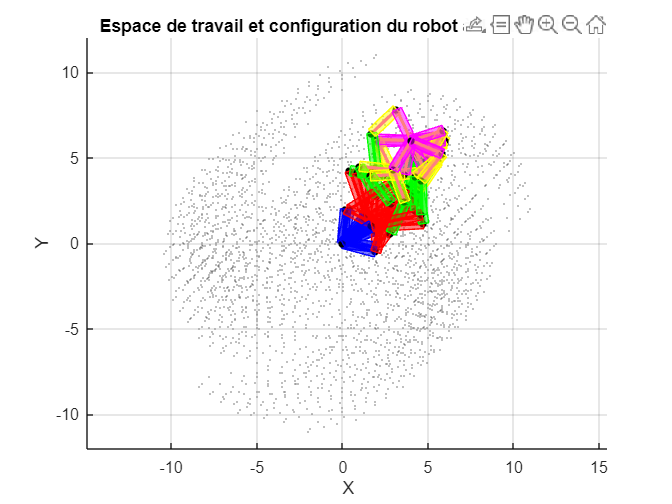

% Définir les couleurs pour chaque type de segment
color_segment_OA = 'b'; % Segment OA
color_segment_AB = 'r'; % Segment AB
color_segment_BC = 'g'; % Segment BC
color_segment_CD = 'm'; % Segment CD
color_segment_DE = 'y'; % Segment DE

% Visualisation des configurations du robot
for i = 1:size(all_solutions, 1)
    % Extraire les angles d'articulation pour cette configuration
    theta1 = all_solutions(i, 1);
    theta2 = all_solutions(i, 2);
    theta3 = all_solutions(i, 3);
    theta4 = all_solutions(i, 4);
    theta5 = all_solutions(i, 5);

    % Calcul des positions des articulations du robot avec les valeurs des angles d'articulation calculées
    O = [0, 0]; % Position de l'origine
    A = [a1*cos(theta1), a1*sin(theta1)]; % Position de l'articulation A
    B = A + [a2*cos(theta1+theta2), a2*sin(theta1+theta2)]; % Position de l'articulation B
    C = B + [a3*cos(theta1+theta2+theta3), a3*sin(theta1+theta2+theta3)]; % Position de l'articulation C (extrémité de l'effecteur)
    D = C + [a4*cos(theta1+theta2+theta3+theta4), a4*sin(theta1+theta2+theta3+theta4)]; % Position de l'articulation C (extrémité de l'effecteur)
    E = D + [a5*cos(theta1+theta2+theta3+theta4+theta5), a5*sin(theta1+theta2+theta3+theta4+theta5)]; % Position de l'articulation C (extrémité de l'effecteur)

    % Tracer le robot pour cette configuration 
    plot([O(1), A(1)], [O(2), A(2)], 'LineWidth', 2, 'Color', color_segment_OA, 'DisplayName', ['Segment OA - Solution ', num2str(i)]); % Segment OA
    plot([A(1), B(1)], [A(2), B(2)], 'LineWidth', 2, 'Color', color_segment_AB, 'DisplayName', ['Segment AB - Solution ', num2str(i)]); % Segment AB
    plot([B(1), C(1)], [B(2), C(2)], 'LineWidth', 2, 'Color', color_segment_BC, 'DisplayName', ['Segment BC - Solution ', num2str(i)]); % Segment BC
    plot([C(1), D(1)], [C(2), D(2)], 'LineWidth', 2, 'Color', color_segment_CD, 'DisplayName', ['Segment CD - Solution ', num2str(i)]); % Segment BC
    plot([D(1), E(1)], [D(2), E(2)], 'LineWidth', 2, 'Color', color_segment_DE, 'DisplayName', ['Segment DE - Solution ', num2str(i)]); % Segment BC
    scatter([O(1), A(1), B(1), C(1), D(1), E(1)], [O(2), A(2), B(2), C(2), D(2), E(2)], 20, 'k', 'filled', 'DisplayName', ['Articulations - Solution ', num2str(i)]); % Marques pour les articulations

    % Ajouter des rectangles autour des segments
    rectWidth = 0.3; % Ajustez cette valeur selon vos besoins
    drawSegmentRectangle(O, A, rectWidth, 'b');
    drawSegmentRectangle(A, B, rectWidth, 'r');
    drawSegmentRectangle(B, C, rectWidth, 'g');
    drawSegmentRectangle(C, D, rectWidth, 'y');
    drawSegmentRectangle(D, E, rectWidth, 'm');
  
end 


% Calculer les limites des axes
xlim([-12, 12]); 
ylim([-12, 12]);
axis equal

% Configurer le titre et les étiquettes des axes
title('Espace de travail et configuration du robot à 4 articulations');
xlabel('X');
ylabel('Y');


% Affichage de la grille
grid on;

hold off; 

## **Affichage de l'espace de solutions**

### **Variation de theta pour chaque solution**

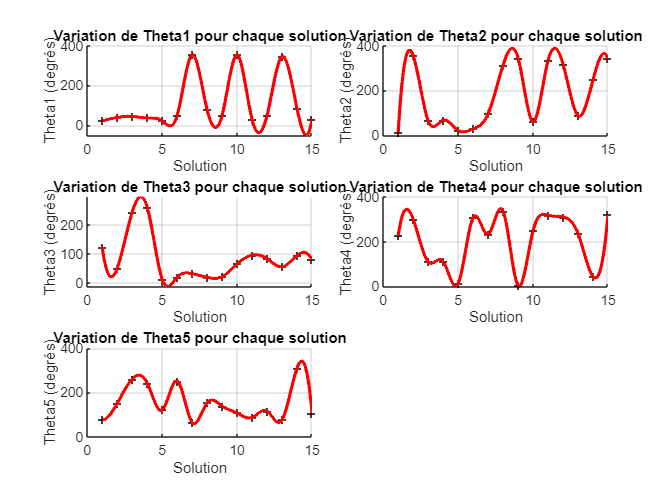

% Définir le nombre total de solutions
num_solutions = size(all_solutions, 1);

% Définir le nombre de lignes et de colonnes pour la grille
num_rows = 3; % Modifier le nombre de lignes selon le nombre de joints
num_cols = 2; % Nombre de colonnes pour afficher les graphiques

% Créer une nouvelle figure
figure;

% Parcourir chaque angle d'articulation
for joint = 1:5
    % Définir la position du subplot dans la grille
    subplot(num_rows, num_cols, joint);
    
    % Titre et étiquettes des axes
    title(['Variation de Theta', num2str(joint), ' pour chaque solution']);
    xlabel('Solution');
    ylabel(['Theta', num2str(joint), ' (degrés)']); % Modification de l'étiquette en degrés
    grid on;

    hold on; % Garder le graphique actif pour ajouter les données de chaque solution

    % Tracer les valeurs des angles d'articulation pour chaque solution en convertissant les radians en degrés
    for i = 1:num_solutions
        % Extraire l'angle d'articulation pour cette solution
        theta_rad = all_solutions(i, joint); % Angle en radians

        % Conversion en degrés
        theta_deg = rad2deg(theta_rad); % Conversion en degrés

        % Tracer l'angle d'articulation pour cette solution
        plot(i, theta_deg, '+', 'DisplayName', ['Solution ', num2str(i)], 'MarkerSize', 5, 'LineWidth', 1, 'Color', 'k');

    end

    % Calculer une interpolation linéaire des données
    x_data = 1:num_solutions; % Les données x sont simplement les indices des solutions
    y_data = rad2deg(all_solutions(:, joint)); % Les données y sont les angles d'articulation convertis en degrés

    % Définir un ensemble de points plus fins pour l'interpolation
    finer_x = linspace(1, num_solutions, 1000); % 1000 points entre le premier et le dernier index

    % Calculer les valeurs interpolées
    interpolated_y = interp1(x_data, y_data, finer_x, 'spline');

    % Tracer la courbe d'interpolation
    plot(finer_x, interpolated_y, 'r-', 'LineWidth', 2, 'DisplayName', 'Interpolation');
end

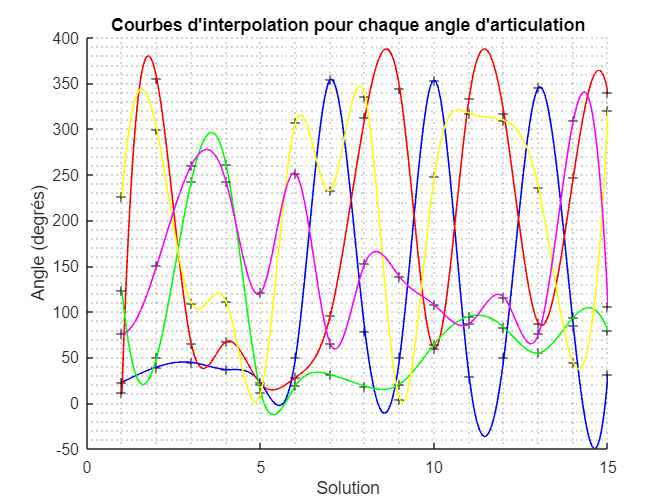





%Courbe de chaque angles 
% Créer une nouvelle figure
figure;

% Titre et étiquettes des axes
title('Courbes d''interpolation pour chaque angle d''articulation');
xlabel('Solution');
ylabel('Angle (degrés)');
grid minor;
hold on; % Garder le graphique actif pour ajouter les données de chaque solution

% Boucle sur chaque angle d'articulation
for joint = 1:5
    % Tracer les valeurs des angles d'articulation pour chaque solution en convertissant les radians en degrés
    for i = 1:num_solutions
        % Extraire l'angle d'articulation pour cette solution
        theta_rad = all_solutions(i, joint); % Angle en radians
        
        % Conversion en degrés
        theta_deg = rad2deg(theta_rad); % Conversion en degrés
        
        % Tracer l'angle d'articulation pour cette solution avec un marqueur plein
        plot(i, theta_deg, '+', 'DisplayName', ['Theta', num2str(joint), ', Solution ', num2str(i)], 'MarkerFaceColor', 'k', 'MarkerEdgeColor', 'k');
    end
    
    % Calculer une interpolation linéaire des données
    x_data = 1:num_solutions; % Les données x sont simplement les indices des solutions
    y_data = rad2deg(all_solutions(:, joint)); % Les données y sont les angles d'articulation convertis en degrés
    
    % Définir un ensemble de points plus fins pour l'interpolation
    finer_x = linspace(1, num_solutions, 1000); % 1000 points entre le premier et le dernier index
    
    % Calculer les valeurs interpolées
    interpolated_y = interp1(x_data, y_data, finer_x, 'spline');
    
    % Couleurs pour chaque angle d'articulation
    colors = ['b', 'r', 'g', 'y', 'm'];
    
    % Tracer la courbe d'interpolation
    plot(finer_x, interpolated_y, '-', 'LineWidth', 1, 'DisplayName', ['Interpolation Theta', num2str(joint)], 'Color', colors(joint));
end

### Positions de des articulations pour chaque solution

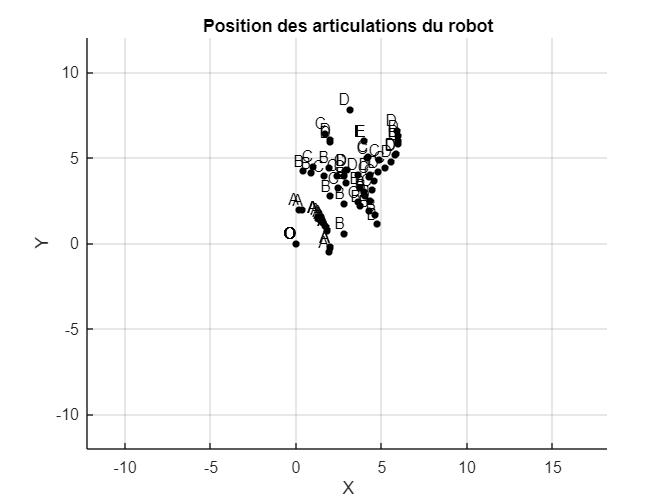

% Créer un graphique distinct pour les articulations du robot
figure;


% Titre et étiquettes des axes
title('Configurations du robot à 4 articulations');
xlabel('Position X');
ylabel('Position Y');

hold on; % Garder le graphique actif pour ajouter les données de chaque solution


% Visualisation des configurations du robot
for i = 1:size(all_solutions, 1)
    % Extraire les angles d'articulation pour cette configuration
    theta1 = all_solutions(i, 1);
    theta2 = all_solutions(i, 2);
    theta3 = all_solutions(i, 3);
    theta4 = all_solutions(i, 4);
    theta5 = all_solutions(i, 5);

    % Calcul des positions des articulations du robot avec les valeurs des angles d'articulation calculées
    O = [0, 0]; % Position de l'origine
    A = [a1*cos(theta1), a1*sin(theta1)]; % Position de l'articulation A
    B = A + [a2*cos(theta1+theta2), a2*sin(theta1+theta2)]; % Position de l'articulation B
    C = B + [a3*cos(theta1+theta2+theta3), a3*sin(theta1+theta2+theta3)]; % Position de l'articulation C (extrémité de l'effecteur)
    D = C + [a4*cos(theta1+theta2+theta3+theta4), a4*sin(theta1+theta2+theta3+theta4)]; % Position de l'articulation C (extrémité de l'effecteur)
    E = D + [a5*cos(theta1+theta2+theta3+theta4+theta5), a5*sin(theta1+theta2+theta3+theta4+theta5)]; % Position de l'articulation C (extrémité de l'effecteur)

    % Tracer le robot pour cette configuration 
    scatter([O(1), A(1), B(1), C(1), D(1), E(1)], [O(2), A(2), B(2), C(2), D(2), E(2)], 20, 'k', 'filled', 'DisplayName', ['Articulations - Solution ', num2str(i)]); % Marques pour les articulations
    % Ajouter les noms des articulations
    text([O(1), A(1), B(1), C(1), D(1), E(1)], [O(2), A(2), B(2), C(2), D(2), E(2)], {'O', 'A', 'B', 'C', 'D', 'E'}, 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
end 
grid on;

% Calculer les limites des axes
xlim([-12, 12]); 
ylim([-12, 12]);
axis equal

% Configurer le titre et les étiquettes des axes
title('Position des articulations du robot');
xlabel('X');
ylabel('Y');

### Graphique separe pour chaque articulation

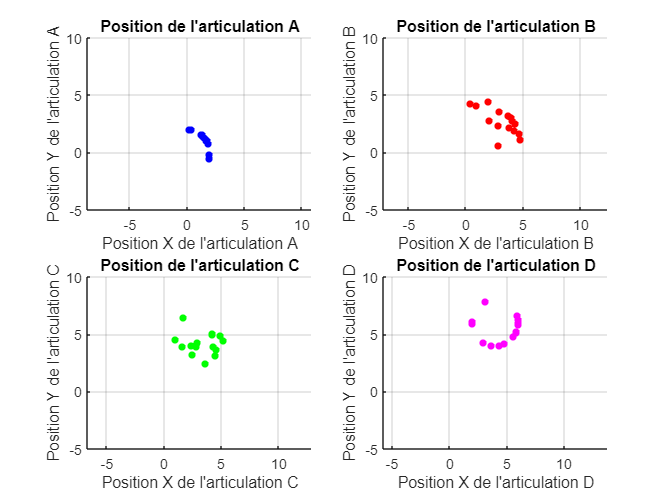

% Créer un graphique distinct pour chaque articulation
figure;

% Articulation A
subplot(2, 2, 1);
title('Position de l''articulation A');
xlabel('Position X de l''articulation A');
ylabel('Position Y de l''articulation A');
hold on;
% Calculer les positions de l'articulation A pour chaque solution
A_positions = zeros(size(all_solutions, 1), 2);
for i = 1:size(all_solutions, 1)
    % Extraire l'angle d'articulation pour cette configuration
    theta1 = all_solutions(i, 1);
    
    % Calculer la position de l'articulation A pour cette solution
    A = [a1*cos(theta1), a1*sin(theta1)]; % Position de l'articulation A
    A_positions(i, :) = A;
end
scatter(A_positions(:, 1), A_positions(:, 2), 20, 'b', 'filled');
grid on;
xlim([-5, 5]); % Définir les limites des axes X
ylim([-5, 10]); % Définir les limites des axes Y

% Articulation B
subplot(2, 2, 2);
title('Position de l''articulation B');
xlabel('Position X de l''articulation B');
ylabel('Position Y de l''articulation B');
hold on;
% Calculer les positions de l'articulation B pour chaque solution
B_positions = zeros(size(all_solutions, 1), 2);
for i = 1:size(all_solutions, 1)
    % Extraire les angles d'articulation pour cette configuration
    theta1 = all_solutions(i, 1);
    theta2 = all_solutions(i, 2);
    
    % Calculer la position de l'articulation B pour cette solution
    B = A_positions(i, :) + [a2*cos(theta1+theta2), a2*sin(theta1+theta2)]; % Position de l'articulation B
    B_positions(i, :) = B;
end
scatter(B_positions(:, 1), B_positions(:, 2), 20, 'r', 'filled');
grid on;
xlim([-5, 5]); % Définir les limites des axes X
ylim([-5, 10]); % Définir les limites des axes Y

% Articulation C
subplot(2, 2, 3);
title('Position de l''articulation C');
xlabel('Position X de l''articulation C');
ylabel('Position Y de l''articulation C');
hold on;
% Calculer les positions de l'articulation C pour chaque solution
C_positions = zeros(size(all_solutions, 1), 2);
for i = 1:size(all_solutions, 1)
    % Extraire les angles d'articulation pour cette configuration
    theta1 = all_solutions(i, 1);
    theta2 = all_solutions(i, 2);
    theta3 = all_solutions(i, 3);
    
    % Calculer la position de l'articulation C pour cette solution
    C = B_positions(i, :) + [a3*cos(theta1+theta2+theta3), a3*sin(theta1+theta2+theta3)]; % Position de l'articulation C
    C_positions(i, :) = C;
end
scatter(C_positions(:, 1), C_positions(:, 2), 20, 'g', 'filled');
grid on;
xlim([-5, 5]); % Définir les limites des axes X
ylim([-5, 10]); % Définir les limites des axes Y

% Articulation D
subplot(2, 2, 4);
title('Position de l''articulation D');
xlabel('Position X de l''articulation D');
ylabel('Position Y de l''articulation D');
hold on;
% Calculer les positions de l'articulation D pour chaque solution
D_positions = zeros(size(all_solutions, 1), 2);
for i = 1:size(all_solutions, 1)
    % Extraire les angles d'articulation pour cette configuration
    theta1 = all_solutions(i, 1);
    theta2 = all_solutions(i, 2);
    theta3 = all_solutions(i, 3);
    theta4 = all_solutions(i, 4);
    
    % Calculer la position de l'articulation D pour cette solution
    D = C_positions(i, :) + [a4*cos(theta1+theta2+theta3+theta4), a4*sin(theta1+theta2+theta3+theta4)]; % Position de l'articulation D
    D_positions(i, :) = D;
end
scatter(D_positions(:, 1), D_positions(:, 2), 20, 'm', 'filled');
grid on;
xlim([-5, 5]); % Définir les limites des axes X
ylim([-5, 10]); % Définir les limites des axes Y

% Réglage des espacements entre les sous-graphiques
subplot(2, 2, 1); axis equal; 
subplot(2, 2, 2); axis equal; 
subplot(2, 2, 3); axis equal; 
subplot(2, 2, 4); axis equal;


% % Définir le nombre total de solutions
% num_solutions = size(all_solutions, 1);
% 
% % Boucle sur chaque articulation
% for joint = 1:5
%     % Créer une nouvelle figure pour chaque articulation
%     figure;
% 
%     % Titre et étiquettes des axes
%     title(['Positions de l''articulation ', num2str(joint)]);
%     xlabel('X');
%     ylabel('Y');
%     grid on;
% 
%     hold on; % Garder le graphique actif pour ajouter les données de chaque solution
% 
%     % Tracer les positions des articulations pour chaque solution
%     for i = 1:num_solutions
%         % Extraire les coordonnées de l'articulation pour cette solution
%         x_joint = all_solutions(i, 6); % Coordonnée X de l'articulation
%         y_joint = all_solutions(i, 7); % Coordonnée Y de l'articulation
% 
%         % Tracer la position de l'articulation pour cette solution
%         scatter(x_joint, y_joint, 100, 'filled', 'DisplayName', ['Solution ', num2str(i)]);
%     end
% 
%     % Légende
%     legend('Location', 'best');
% end
% Pour l'articulation A

% Pour l'articulation A

% Créer un graphique distinct pour l'articulation A
figure;

% 
% % Créer un graphique distinct pour chaque solution
% for i = 1:size(all_solutions, 1)
%     % Créer une nouvelle figure pour chaque solution
%     figure;
% 
%     % Extraire les angles d'articulation pour cette configuration
%     theta1 = all_solutions(i, 1);
%     theta2 = all_solutions(i, 2);
%     theta3 = all_solutions(i, 3);
%     theta4 = all_solutions(i, 4);
%     theta5 = all_solutions(i, 5);
% 
%     % Calculer les positions des articulations pour cette configuration
%     O = [0, 0]; % Position de l'origine
%     A = [a1*cos(theta1), a1*sin(theta1)]; % Position de l'articulation A
%     B = A + [a2*cos(theta1+theta2), a2*sin(theta1+theta2)]; % Position de l'articulation B
%     C = B + [a3*cos(theta1+theta2+theta3), a3*sin(theta1+theta2+theta3)]; % Position de l'articulation C
%     D = C + [a4*cos(theta1+theta2+theta3+theta4), a4*sin(theta1+theta2+theta3+theta4)]; % Position de l'articulation D
%     E = D + [a5*cos(theta1+theta2+theta3+theta4+theta5), a5*sin(theta1+theta2+theta3+theta4+theta5)]; % Position de l'articulation E
% 
%     % Tracer les positions des articulations pour cette solution
%     plot([O(1), A(1), B(1), C(1), D(1), E(1)], [O(2), A(2), B(2), C(2), D(2), E(2)], 'o-', 'DisplayName', ['Solution ', num2str(i)]);
% 
%     % Configurer le titre et les étiquettes des axes
%     title(['Positions des articulations pour la solution ', num2str(i)]);
%     xlabel('Position X');
%     ylabel('Position Y');
%     legend('Location', 'best');
%     grid on;
% end
% 


### Fonctions

% Fonction cinematique inverse et pour créer un rectangle autour d'un segment

function drawSegmentRectangle(startPoint, endPoint, rectWidth, color)
    % Calcule la longueur et l'angle du segment
    segmentLength = norm(endPoint - startPoint);
    segmentAngle = atan2(endPoint(2) - startPoint(2), endPoint(1) - startPoint(1));
    
    % Calcule les coordonnées des coins du rectangle
    dx = rectWidth * cos(segmentAngle + pi/2);
    dy = rectWidth * sin(segmentAngle + pi/2);
    rectPoints = [startPoint(1) - dx, startPoint(2) - dy;
                  startPoint(1) + dx, startPoint(2) + dy;
                  endPoint(1) + dx, endPoint(2) + dy;
                  endPoint(1) - dx, endPoint(2) - dy;
                  startPoint(1) - dx, startPoint(2) - dy];
    
    % Trace le rectangle
    fill(rectPoints(:, 1), rectPoints(:, 2), color, 'EdgeColor', color, 'FaceAlpha', 0.5);
end

function [all_solutions] = find_inverse_kinematics(a1, a2, a3, a4, a5, x_desired, y_desired, num_configurations)
    % Définir les angles d'articulation
    syms theta1 theta2 theta3 theta4 theta5;
    % Définir une tolérance et un nombre maximum d'itérations
    tolerance = 0.0000001;
    max_iterations = 100;
   % Initialiser une liste pour stocker les configurations atteignables
    all_solutions = [];

    % Recherche des configurations
    while size(all_solutions, 1) < num_configurations
        % Initialiser les angles d'articulation
        theta1 = rand * 2 * pi; % Initialiser à des valeurs aléatoires
        theta2 = rand * 2 * pi;
        theta3 = rand * 2 * pi;
        theta4 = rand * 2 * pi;
        theta5 = rand * 2 * pi;

        % Boucle d'itération pour trouver les angles d'articulation
        for i = 1:max_iterations
            % Calculer les équations directes de cinématique directe
            x = a1*cos(theta1) + a3*cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - a3*sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + a2*cos(theta1)*cos(theta2) - a2*sin(theta1)*sin(theta2) + a5*cos(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)))) + a4*cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))) + sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)))) - a4*sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)));
            y = a1*sin(theta1) + a3*cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + a3*sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) + a2*cos(theta1)*sin(theta2) + a2*cos(theta2)*sin(theta1) + a5*cos(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))) + sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)))) + a4*cos(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))) + a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)))) + a4*sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)));
          
            % Calculer l'erreur de position
            error_x = x_desired - x;
            error_y = y_desired - y;
            error = [error_x; error_y];

            % Calculer les dérivées partielles
            dx_dtheta1 = -a1*sin(theta1) - a3*cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - a3*sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) - a2*sin(theta1)*sin(theta2) - a2*cos(theta1)*cos(theta2) - a4*sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))));
            dx_dtheta2 = -a3*cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - a3*sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + a2*cos(theta1)*cos(theta2) - a2*sin(theta1)*sin(theta2) - a4*sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))));
            dx_dtheta3 = a3*sin(theta3)*(sin(theta1)*sin(theta2) - cos(theta1)*cos(theta2)) + a4*sin(theta4)*(sin(theta1)*sin(theta2) - cos(theta1)*cos(theta2)) + a5*sin(theta5)*(sin(theta1)*sin(theta2) - cos(theta1)*cos(theta2));
            dx_dtheta4 = -a4*sin(theta4)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - a5*sin(theta5)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2));
            dx_dtheta5 = -a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))) + a5*cos(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))) - sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)))));
    
            dy_dtheta1 = a1*cos(theta1) + a3*cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + a3*sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) + a2*cos(theta2)*sin(theta1) + a2*cos(theta1)*sin(theta2) + a4*cos(theta4)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) + a5*cos(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))) + sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)))) + a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))));
            dy_dtheta2 = a3*cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + a3*sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - a2*sin(theta1)*sin(theta2) - a2*cos(theta1)*cos(theta2) - a4*sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))));
            dy_dtheta3 = - a3*sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + a4*sin(theta4)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + a5*sin(theta5)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1));
            dy_dtheta4 = - a4*sin(theta4)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) - a5*sin(theta5)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1));
            dy_dtheta5 = a5*cos(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))) - sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) + sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)))));
    
            % Construire la Jacobienne
            J = [dx_dtheta1, dx_dtheta2, dx_dtheta3, dx_dtheta4, dx_dtheta5; 
             dy_dtheta1, dy_dtheta2, dy_dtheta3, dy_dtheta4, dy_dtheta5];
    
            % Vérifier la convergence
            if norm(error) < tolerance
                %disp('Convergence atteinte.');
                % Stocker la solution
                all_solutions = [all_solutions; [theta1, theta2, theta3, theta4, theta5, x, y]];
                
                break;
            end

            % Calculer la variation des angles d'articulation
            delta_theta = pinv(J) * error;
    
            % Mettre à jour les angles d'articulation
            theta1 = theta1 + delta_theta(1);
            theta2 = theta2 + delta_theta(2);
            theta3 = theta3 + delta_theta(3);
            theta4 = theta4 + delta_theta(4);
            theta5 = theta5 + delta_theta(5);

            % Correction des angles d'articulation pour les maintenir entre 0 et 2*pi
            theta1 = mod(theta1, 2*pi);
            theta2 = mod(theta2, 2*pi);
            theta3 = mod(theta3, 2*pi);
            theta4 = mod(theta4, 2*pi);
            theta5 = mod(theta5, 2*pi);
        end
    end
     % Afficher toutes les configurations trouvées
    disp('Configurations possibles du robot pour la position désirée :');
    disp('    Theta1   Theta2    Theta3    Theta4    Theta5  X_calculated   Y_calculated');
    disp(all_solutions);  
    % Afficher toutes les configurations trouvées
    disp('Configurations possibles du robot pour la position désirée :');
    disp('    Theta1 (deg)   Theta2 (deg)   Theta3 (deg)   Theta4 (deg)   Theta5 (deg)   X_calculé   Y_calculé');
    % Convertir les angles de radians en degrés et afficher les résultats
    disp([rad2deg(all_solutions(:, 1:5)), all_solutions(:, 6:7)]);
end